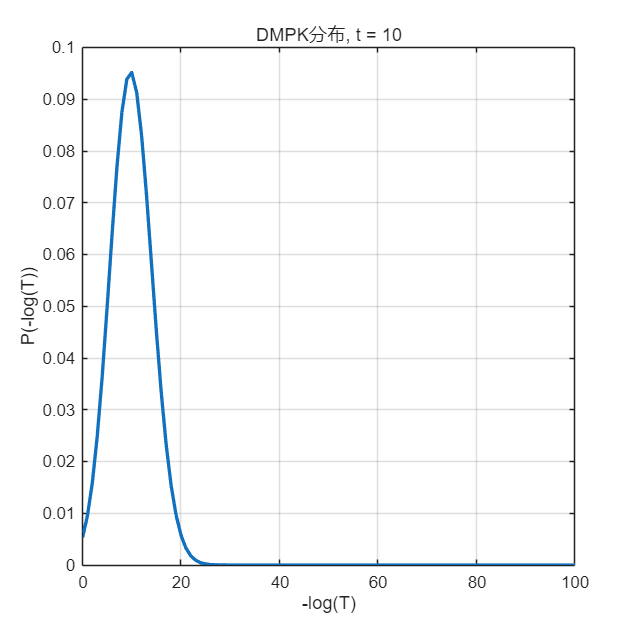

<-log(T)>        = 10.000000
<log(T)^2>       = 116.774187
Std dev(log(T))  = 4.095630
<T>              = 0.010633
-log(<T>)        = 4.543797
<T^2>            = 0.003696
Std dev(T)       = 0.059862


dmpk_plot(10, 100, 100)



function dmpk_plot(t, t_max, nsteps)
% DMPK分布计算与作图
% t: -average_log_transmission
% t_max: 最大-log(T)
% nsteps: 步数

if nargin < 3
    error('用法: dmpk_plot(t, t_max, nsteps)');
end
if t < 0
    error('t 必须为正');
end

t_step = t_max / nsteps;
minus_log_T = linspace(0, t_max, nsteps+1);
rho = exp(minus_log_T);

% 定义被积函数
% This is the integrand in eq.(16) of Abrikosov, Solid State Comm. 37, 997 (1981)


$$W(\rho,t)=\frac{2}{\sqrt{\pi t^3}}\int_{\cosh^{-1}\sqrt{\rho}}^\infty\frac{x\exp[-(x^2/t+t/4)]dx}{\sqrt{\cosh^2x-\rho}}$$


$\rho =\rho \;\left(L\right)$为关于长度的电阻，$t=\frac{L}{l_2 }$,其中$l_2$是背散射平均自由程，从而$t$是根据平均自由程约化的无量纲长度

当平均自由程越短，透射率


% t is the length of the sample is localization length
% rho is 1/T (T is the transmission)
integrand = @(y, rho, t) 2 .* y .* exp(-(y.^2 ./ t + 0.25*t)) ./ sqrt(cosh(y).^2 - rho);

% W函数 This is the W function of Abrikosov
W = @(rho, t) arrayfun(@(r) integral(@(y) integrand(y, r, t), acosh(sqrt(r)), acosh(sqrt(r)) + 5*sqrt(t), 'RelTol',1e-4), rho) ...
    ./ sqrt(pi * t^3);

% This computes the distribution of the -log(T) variable
% It is simply deduced from W(rho) because rho=1/T=exp(minus_log_T)
% 计算分布
Wvals = rho .* W(rho, t);

% 作图
figure;
plot(minus_log_T, Wvals, 'LineWidth', 2);
xlabel('-log(T)');
ylabel('P(-log(T))');
title(['DMPK分布, t = ', num2str(t)]);
grid on;

归一化条件为


$$\int_1^\infty W(\rho,t)d\rho=\int_0^\infty W(e^z,t)e^z dz=1$$


由于对数电阻(电导)具有良好的统计意义，故使用$z=\ln \;\rho \;$,而透射率则对应为电阻倒数$T=\frac{1}{\rho }=e^{-z}$

% 归一化检查
norm = integral(@(mlt) exp(mlt) .* W(exp(mlt), t), 0, t_max, 'RelTol',1e-4);
if abs(norm - 1) > 0.01
    warning(['归一化有问题: norm = ', num2str(norm)]);
end

% 统计量
avg_minus_log_T = integral(@(mlt) mlt .* exp(mlt) .* W(exp(mlt), t), 0, t_max, 'RelTol',1e-4);
avg_minus_log_T2 = integral(@(mlt) mlt.^2 .* exp(mlt) .* W(exp(mlt), t), 0, t_max, 'RelTol',1e-4);
avg_T = integral(@(mlt) W(exp(mlt), t), 0, t_max, 'RelTol',1e-4);
avg_T2 = integral(@(mlt) exp(-mlt) .* W(exp(mlt), t), 0, t_max, 'RelTol',1e-4);

fprintf('<-log(T)>        = %.6f\n', avg_minus_log_T / norm);
fprintf('<log(T)^2>       = %.6f\n', avg_minus_log_T2 / norm);
fprintf('Std dev(log(T))  = %.6f\n', sqrt(avg_minus_log_T2 / norm - (avg_minus_log_T / norm)^2));
fprintf('<T>              = %.6f\n', avg_T / norm);
fprintf('-log(<T>)        = %.6f\n', -log(avg_T / norm));
fprintf('<T^2>            = %.6f\n', avg_T2 / norm);
fprintf('Std dev(T)       = %.6f\n', sqrt(avg_T2 / norm - (avg_T / norm)^2));
end